# ThermoeconomicTool demo

Analyze an ORC system, and compare two system configurations:

(1) Produce only electricity working at 30°C condensing temperature (TCND30)

(2) Produce electricity and low-temperature heat for a refrigeration cycle, working at a condensing temperature of 50ºC (TCND50)

**(1) Read data model **

Read the data file and create the model with some parameters. 

model=ThermoeconomicTool('rorc_model.xlsx',...
    'State','TCND30',...
    'CostTables','ALL',...
    'DiagnosisMethod','NONE',...
    'Debug',false);

**(2) Print the results for TCND30**

Print the model results and show the ICT graph

printResults(model);

Flows Definition Table

  Id Key   From    To      Type      
——————————————————————————————————————
   1 B1    BLR_P1  TRB_F1  INTERNAL  
   2 B2    TRB_F1  IHE_F1  INTERNAL  
   3 B3    IHE_F1  CND_F1  INTERNAL  
   4 B4    CND_F1  PMP_P1  INTERNAL  
   5 B5    PMP_P1  IHE_P1  INTERNAL  
   6 B6    IHE_P1  BLR_P1  INTERNAL  
   7 QBLR  ENV_R1  BLR_F1  RESOURCE  
   8 WP    TRB_P1  PMP_F1  INTERNAL  
   9 WN    TRB_P1  ENV_O1  OUTPUT    
  10 QCND  CND_P1  ENV_W1  WASTE     


Productive Groups Definition Table

  Id Key     Definition  Type      
————————————————————————————————————
   1 BLR_F1  QBLR        FUEL      
   2 BLR_P1  B1-B6       PRODUCT   
   3 TRB_F1  B1-B2       FUEL      
   4 TRB_P1  WN+WP       PRODUCT   
   5 IHE_F1  B2-B3       FUEL      
   6 IHE_P1  B6-B5       PRODUCT   
   7 PMP_F1  WP          FUEL      
   8 PMP_P1  B5-B4       PRODUCT   
   9 CND_F1  B3-B4       FUEL      
  10 CND_P1  QCND        PRODUCT   
  11 ENV_R1  QBLR        RESOURCE  
  12 ENV_O1 

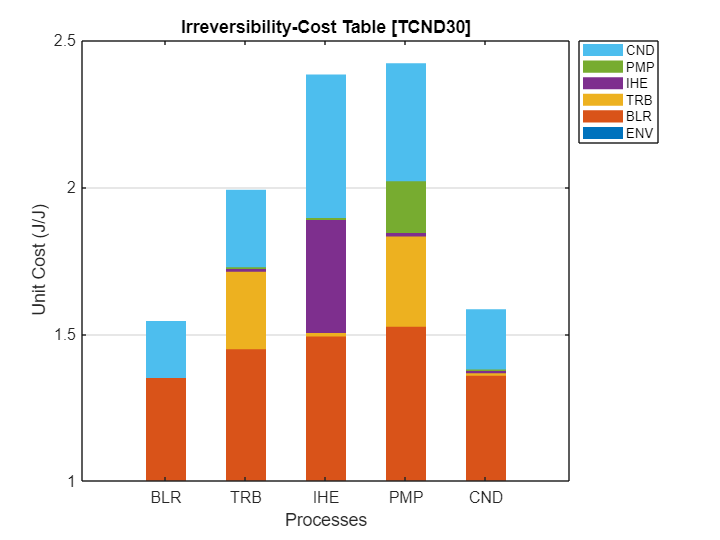

model.showGraph(cType.Tables.PROCESS_ICT);

**(3) Build model FPR for state TCND50**

Define the TCND50 conditions for recycling and show the Waste Allocation piechart and the ICT graph

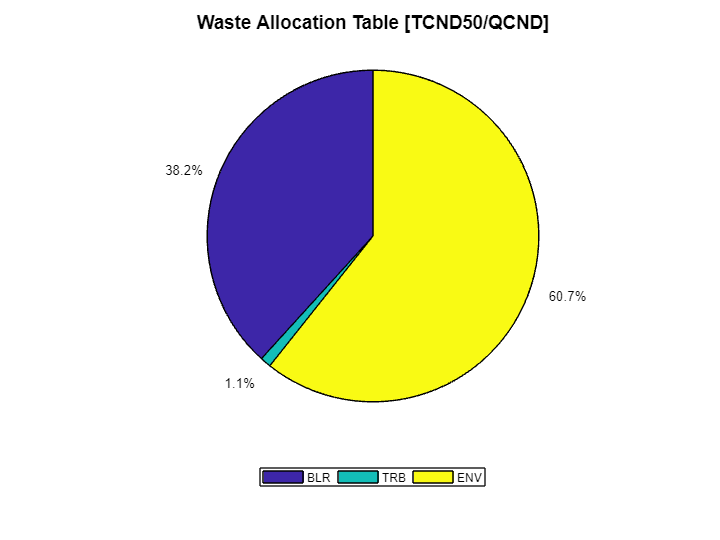

model.State='TCND50';
model.setWasteRecycled(model.ActiveWaste,0.6);
model.showGraph(cType.Tables.WASTE_ALLOCATION);

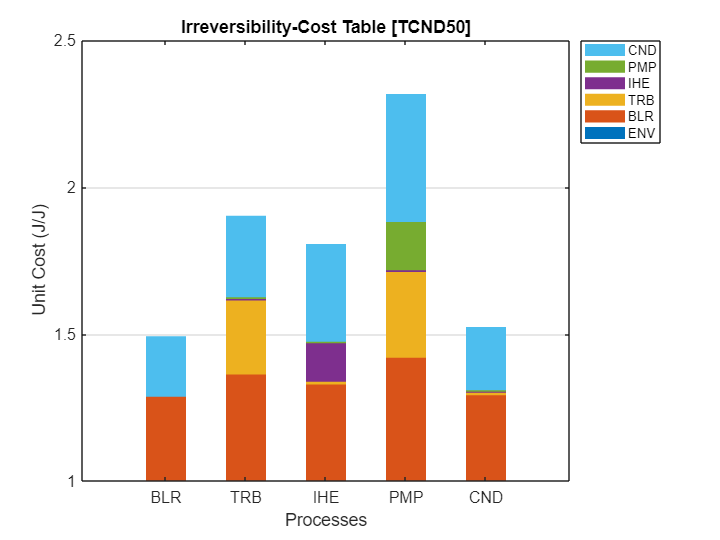

model.showGraph(cType.Tables.PROCESS_ICT);

**(4) Plot the recycling analysis graph**

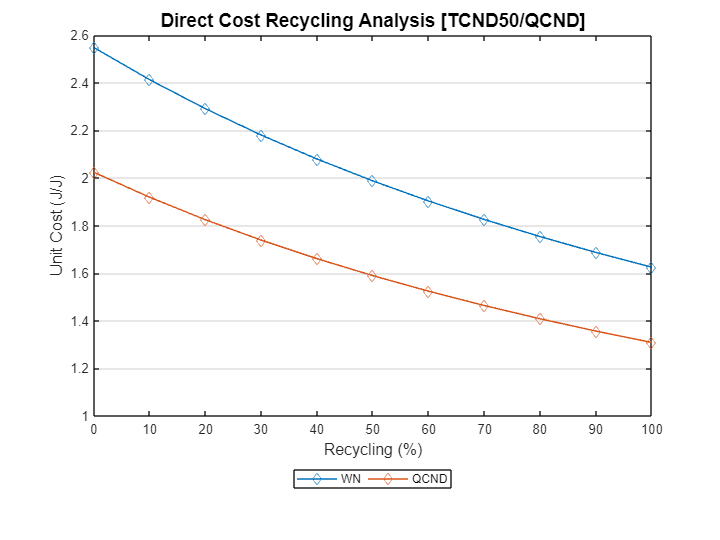

model.Recycling=true;
res=model.wasteAnalysis;
res.showGraph(cType.Tables.WASTE_RECYCLING_DIRECT);

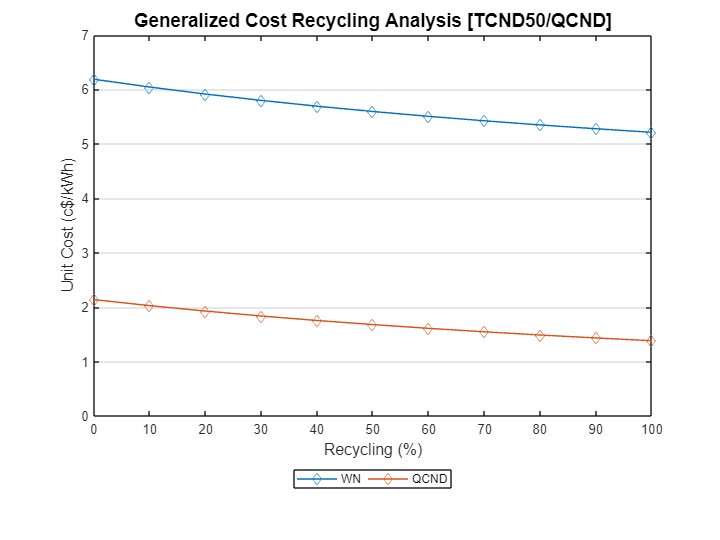

res.showGraph(cType.Tables.WASTE_RECYCLING_GENERAL);

**(5) Compare both configurations**

Compare both states using the thermoeconomicDiagnosis function

model.DiagnosisMethod='WASTE_INTERNAL';
model.summaryDiagnosis;

Fuel Impact:    -9.1900 (kW)
Malfunction Cost:   -25.1125 (kW)


model.printTable('dgn');

Diagnosis Summary

Key        MF(kW)      ΔI(kW)     ΔPt(kW)     MF*(kW)     MR*(kW)    ΔPs*(kW)
——————————————————————————————————————————————————————————————————————————————
BLR       -4.6938     -5.6960      0.0000     -4.6938    -11.7585      0.0000
TRB       -0.5548     -4.0880    -14.5000     -0.5908     -0.2790    -23.5585
IHE       -0.3709     -0.2700      0.0000     -0.4810     -0.2556      0.0000
PMP       -0.0236     -0.0370      0.0000     -0.0383     -0.1602      0.0000
CND        0.0000     -9.5170     24.9180      0.0197      0.0000     32.6061
ENV       -5.6431    -19.6080     10.4180     -5.7843    -12.4533      9.0476



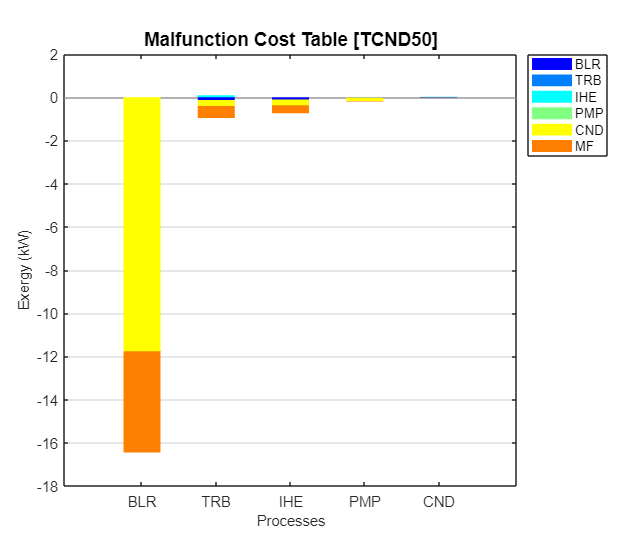

ShowGraph(model,'Graph','mfc','ShowOutput',false);

**(6) Show Summary Results**

Show unit cost summary tables and graph

model.printTable(cType.Tables.SUMMARY_FLOW_UNIT_COST);

Summary Flows Direct Unit Exergy Cost (J/J)

 Key       TCND30     TCND35     TCND50      TRB75     PBLR16      IHE60      noIHE
————————————————————————————————————————————————————————————————————————————————————
 B1        1.5844     1.6768     1.3085     1.5856     1.6182     1.6128     1.6939
 B2        1.5844     1.6768     1.3085     1.5856     1.6182     1.6128     1.6939
 B3        1.5844     1.6768     1.3085     1.5856     1.6182     1.6128     1.6939
 B4        1.5844     1.6768     1.3085     1.5856     1.6182     1.6128     1.6939
 B5        1.8078     1.9103     1.4174     1.8479     1.8084     1.8398     1.9337
 B6        1.9008     1.9950     1.4275     1.9550     1.9020     1.9750     1.9337
 QBLR      1.0000     1.0000     1.0000     1.0000     1.0000     1.0000     1.0000
 WP        1.9906     2.1065     1.6247     2.1155     2.0341     2.0261     2.1284
 WN        1.9906     2.1065     1.6247     2.1155     2.0341     2.0261     2.1284
 QCND      1.5844     1.6768  

model.printTable(cType.Tables.SUMMARY_FLOW_GENERAL_UNIT_COST);

Summary Flows Generalized Unit Cost (c$/kWh)

 Key       TCND30     TCND35     TCND50      TRB75     PBLR16      IHE60      noIHE
————————————————————————————————————————————————————————————————————————————————————
 B1        1.2511     1.3438     0.9516     1.2616     1.2917     1.2654     1.2655
 B2        1.2511     1.3438     0.9516     1.2616     1.2917     1.2654     1.2655
 B3        1.2511     1.3438     0.9516     1.2616     1.2917     1.2654     1.2655
 B4        1.2511     1.3438     0.9516     1.2616     1.2917     1.2654     1.2655
 B5        2.6245     2.7253     2.1194     2.7285     2.5728     2.6397     2.6387
 B6        2.8042     2.8570     2.1312     2.8856     2.7931     2.9254     2.6387
 QBLR      0.5000     0.5000     0.5000     0.5000     0.5000     0.5000     0.5000
 WP        4.4793     4.8264     5.2118     4.7864     4.8117     4.4971     4.4969
 WN        4.4793     4.8264     5.2118     4.7864     4.8117     4.4971     4.4969
 QCND      2.3806     2.1229 

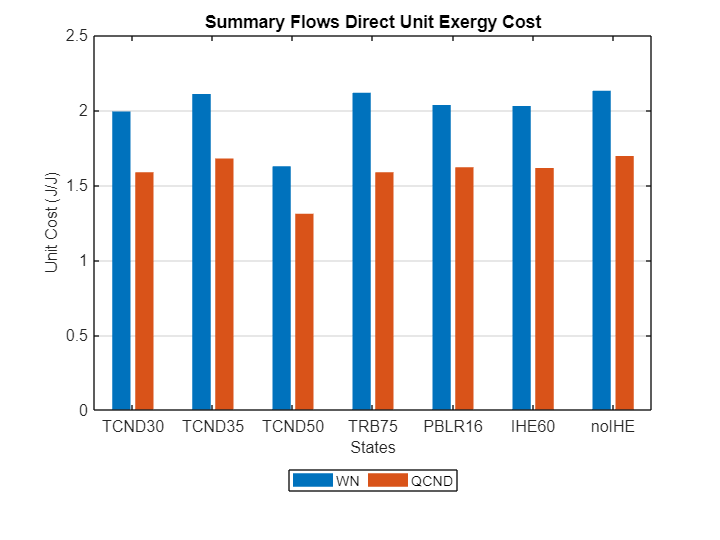

model.showGraph(cType.Tables.SUMMARY_FLOW_UNIT_COST);

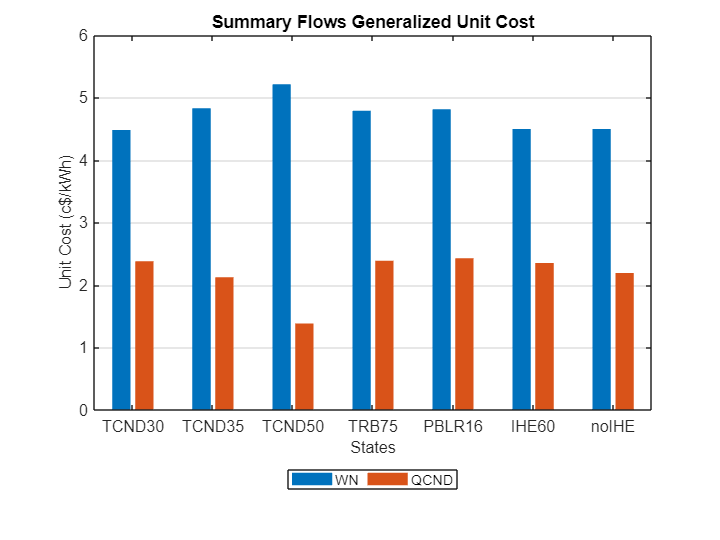

model.showGraph(cType.Tables.SUMMARY_FLOW_GENERAL_UNIT_COST);